# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 11 REPORT**

**JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

VLFeat configuration:

clear all;
VLFEAT_DIR = 'VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));
vl_version;

0.9.20


a) 

First, train the model with a subset of categories:

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 600
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 2.49 s
kmeans: Elkan iter 0: energy = 9.24014e+09, dist. calc. = 42075999
kmeans: Elkan iter 1: energy <= 6.3631e+09, dist. calc. = 8807751
kmeans: Elkan iter 2: energy <= 6.12987e+09, dist. calc. = 7365881
kmeans: Elkan iter 3: energy <= 6.029e+09, dist. calc. = 6370590
kmeans: Elkan iter 4: energy <= 5.97225e+09, dist. calc. = 5148164
kmeans: Elkan iter 5: energy <= 5.93833e+09, dist. calc. = 3979508
kmeans: Elkan iter 6: energy <= 5.91658e+09, dist. calc. = 3141040
kmeans: Elkan iter 7: energy <= 5.90139e+09, dist. calc. = 2623152
kmeans: Elkan iter 8: energy <= 5.89008e+09, dist. 

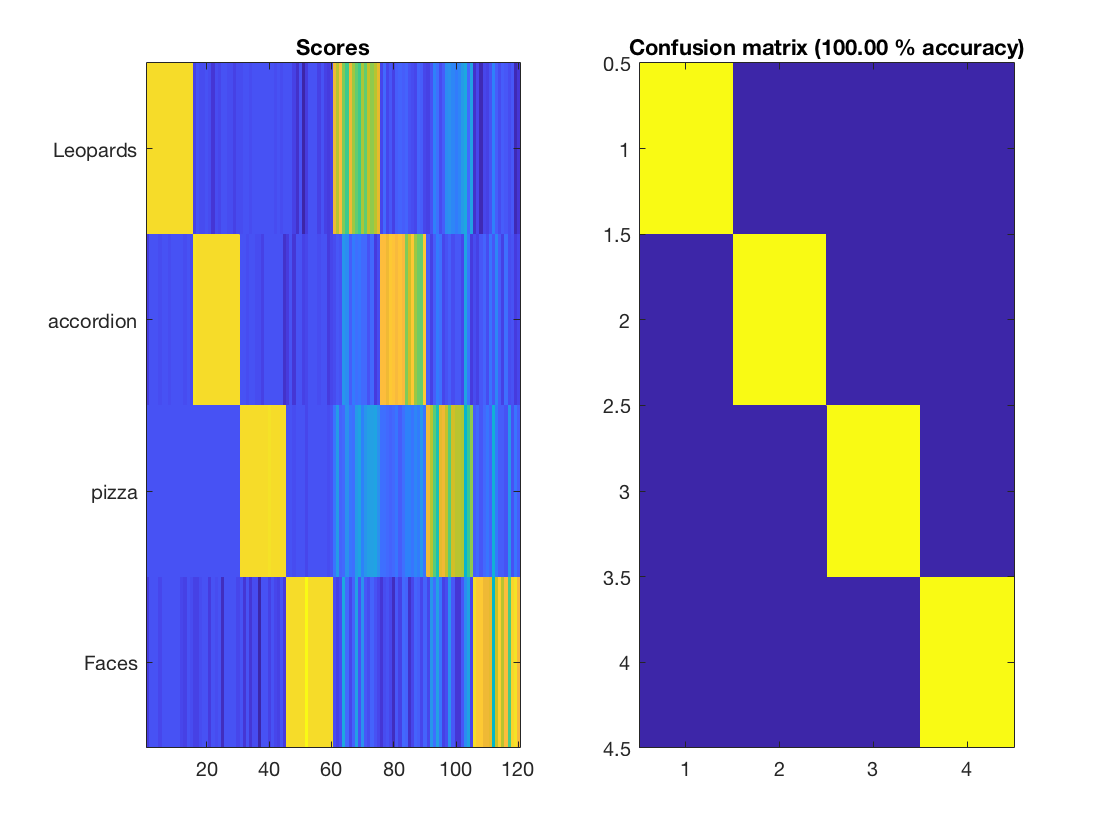

categorySubset = { 'Leopards', 'accordion', 'pizza', 'Faces' };
modified_phow_caltech101(categorySubset);

Add a function to train visualize the images in a green framework if the classification is correct and in a red framework if it does not:

/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0056.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0056.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0141.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0141.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0125.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Leopards/image_0125.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_

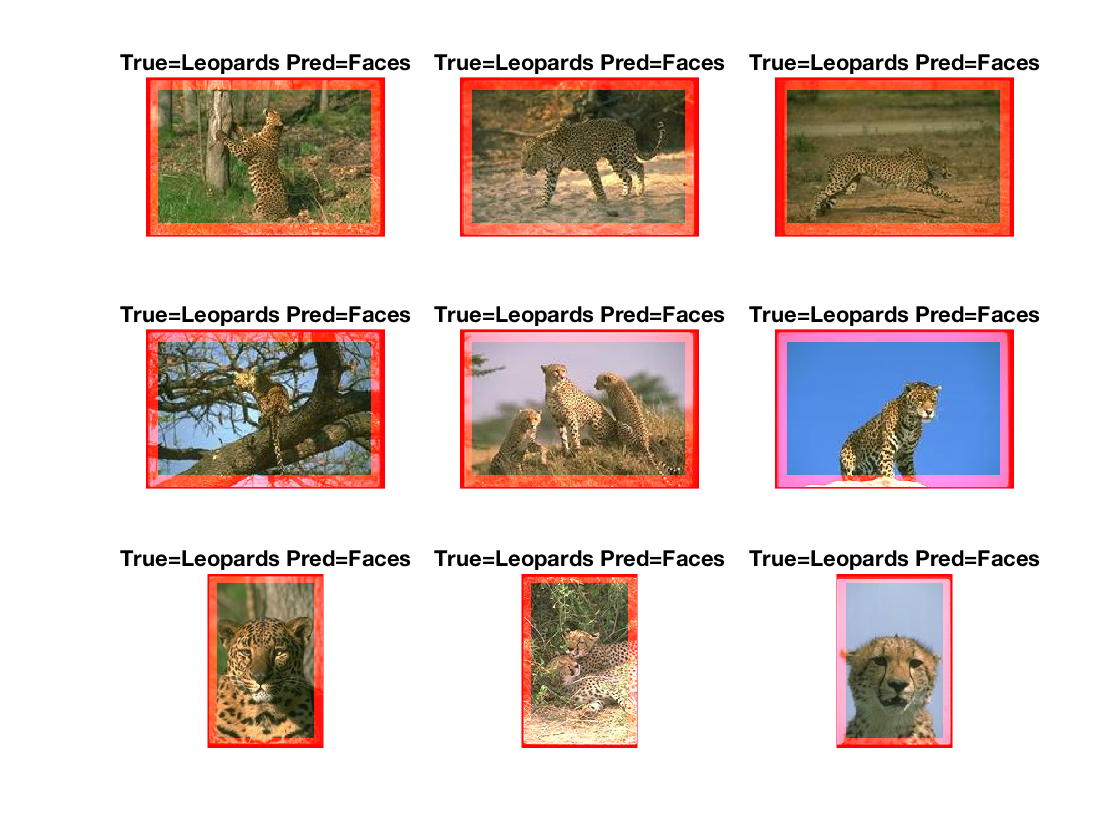

% 
% Choose imageCount random images to classify and draw border around
% 
categorySubset = { 'Leopards', 'accordion', 'pizza', 'Faces' };
imageCount = 9;
modelPath = fullfile('data','baseline-model.mat');
imageBaseDir = fullfile('data','caltech-101','101_ObjectCategories');
imagePaths = buildImagePaths(imageBaseDir, categorySubset);
visualizeImgClass(imagePaths, modelPath);

b) 

*What are the PHOW descriptors?  *

They represent the Pyramid Histogram Of visual Words. 

The function to obtain them is 

%[FRAMES, DESCRS] = vl_phow(IMG)

DESCRS, Each column of DESCRS is the descriptor of the corresponding frame in FRAMES. A descriptor is a 128-dimensional vector of class UINT8.

It represents a 4x4 spatial histogram of gradient orientations, each with 8 different directions, leading to a 4x4x8=128 dimensional vector.

FRAMES(1:2,:) are the x,y coordinates of the center of each descriptor, FRAMES(3,:) is the contrast of the descriptor, as returned by VL_DSIFT() (for colour variant, contranst is computed on the intensity channel). FRAMES(4,:) is the size of the bin of the descriptor.

*What does the Sizes parameter mean? *

It's the scales at which the dense SIFT features are extracted. Each value is used as the spatial bin size in pixels when extracting a dense set of SIFT features from the image.

*What does happen if the Sizes parameter is augmented? *

From the lectures, the code to calculate the phow descriptors:

% step = 5;
% for size=[5,7,10,12]
%     [x,y]=meshgrid(1:step:width, 1:step:height);
%     frames = [x(:)'; y(:)'];
%     frames(3,:) = size/3;
%     frames(4,:) = 0;
%     [frames, descrs] = vl_sift(im, 'Frames', frames);
% end

It can be observed that if the size is increased the size of the bin of the descriptor is increased.				

*What does the Step parameter mean?* 

Step (in pixels) of the grid at which the dense SIFT features are extracted.

*What does happen if the Step parameter is augmented?*

If the step parameter is augmented, then a grid with a lower resolution is created, and less features are extracted.

c) 

*What are the words in the algorithm?* 

*How are they extracted?* 

*What is their dimension?* 

*How their number does affect the accuracy of the results? *

vocab = open('data/baseline-vocab.mat')

vocab = struct with fields:
    vocab: [128×600 single]


We observe that the vocab consists of 128x600. The 128 represents the 128 dimensions of the sift descriptors generated by *vl_phow*, as explained before. The 600 columns represent one word each. To extract the vocab, k-means is applied to the sift descriptors. Each word of the vocab represents the centre of the k-means clusters found. From the phow function code:

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 600
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 2.19 s
kmeans: Elkan iter 0: energy = 9.16197e+09, dist. calc. = 41606807
kmeans: Elkan iter 1: energy <= 6.34265e+09, dist. calc. = 8196540
kmeans: Elkan iter 2: energy <= 6.11386e+09, dist. calc. = 6369357
kmeans: Elkan iter 3: energy <= 6.01142e+09, dist. calc. = 5916580
kmeans: Elkan iter 4: energy <= 5.95205e+09, dist. calc. = 4916099
kmeans: Elkan iter 5: energy <= 5.9145e+09, dist. calc. = 3925777
kmeans: Elkan iter 6: energy <= 5.88743e+09, dist. calc. = 3246364
kmeans: Elkan iter 7: energy <= 5.86817e+09, dist. calc. = 2808637
kmeans: Elkan iter 8: energy <= 5.85377e+09, dist

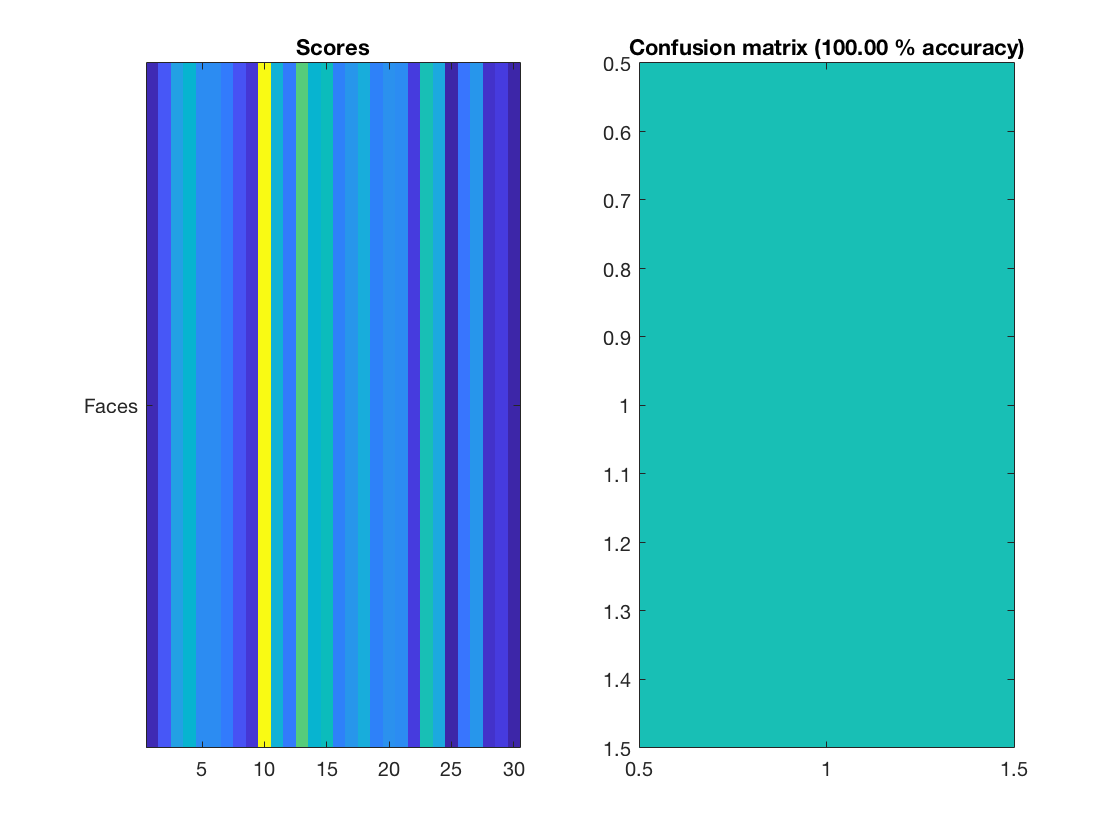

% vocab = vl_kmeans(descrs, conf.numWords, 'verbose', 'algorithm', 'elkan', 'MaxNumIterations', 50) ;
words = 600;
categorySubset = {'Faces'};
modified_phow_caltech101(categorySubset, words);

/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0122.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0122.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0306.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0306.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0272.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/caltech-101/101_ObjectCategories/Faces/image_0272.jpg
/Users/jnalexander/Projects/computer_vision/EmerRodriguezFormisano+JorgeAlexander_CV_Lab11/data/calt

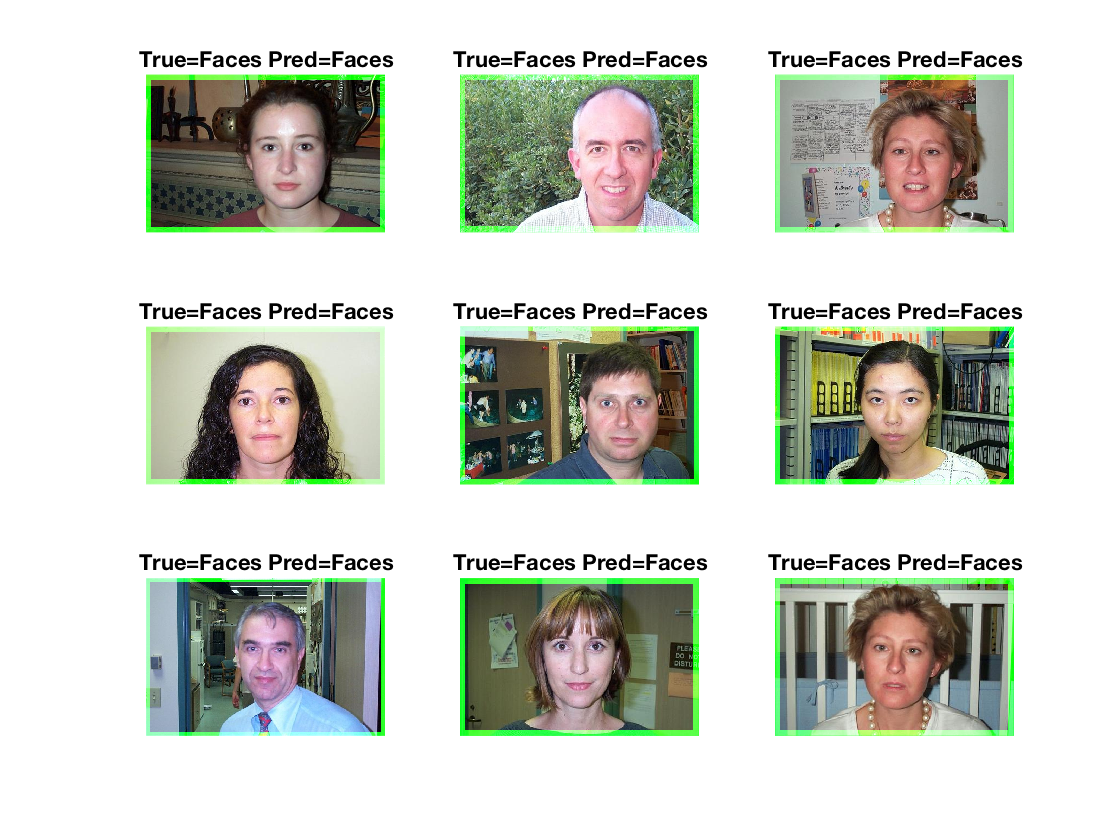

imagePaths = buildImagePaths(imageBaseDir, categorySubset);
visualizeImgClass(imagePaths, modelPath);